# **Semi Random Monte Carlo Diffusion Model**

 Made by Eddie Cunning n11040076

Supervisor Konstantin Momot

Progress bar by [Ameer Hamza](https://www.mathworks.com/matlabcentral/answers/599287-progress-bar-and-for-loop)

clear
test_num = 5;

### Setting Variables


Nt = 20000; % Number of Time Steps
Np = 10000; % Number of Particles

theta = deg2rad(60); % Angle of the fibre from the Z axis. Converted to radians, as are all of the angles to reduce later calculations as MATLAB works in rad

D_0 = 2.3 * 10^-9;

delta_t = 5 * 10^-9;

delta_r = sqrt(6 * D_0 * delta_t);

box_xyz = 200 * 10^-9; % half side length of cube length in nm, 200*10^-9 for 400nm across. must all be the same.

fibre = [-100 * 10^-9, 100 * 10^-9
     100 * 10^-9, 100 * 10^-9
     -100 * 10^-9, -100 * 10^-9
     100 * 10^-9, -100 * 10^-9]; % Cartesian starting Position of each fibre, each is at -cube_z in the z direction

fibre_radius = 60 * 10^-9; % fibre radius

### Setting Fibre Angle

r_angles = 360 * rand(1, 4);
phi = [deg2rad(r_angles(1))
     deg2rad(r_angles(2))
     deg2rad(r_angles(3))
     deg2rad(r_angles(4))];


### **Setting Fibre Dots**

% A grid of dots is layed out in an array, and then each is associated as
% either inside a fibre or outside. When a particle moves, it then looks
% for the closest dot to determine if it is inside the fibre or not
% the dots are used as a percentage to determine the volume of the fibres
% when fibres cannot intersect, the dots will be checked to see if they
% take up the same space.
grid_points = 51; % number of dots in each direction, must be odd to have centre fots

grid_8 = (grid_points - 1) / 2; %the number of dots from the centre to the edge in one direction
grid_zero = grid_points^2 * grid_8 + grid_points * grid_8 + grid_8 + 1; % middle point
total_dots = grid_points^3;
dot_dist = 2 * box_xyz(1)/grid_points;
dots = zeros(3, total_dots); % setting array size

dot = 1;

for x = -grid_8:grid_8
    for y = -grid_8:grid_8
        for z = -grid_8:grid_8
            dots(1, dot) = x;
            dots(2, dot) = y;
            dots(3, dot) = z;
            dot = dot + 1;
        end
    end
end

dots = dots * dot_dist; %final position of each dot
single_grid = (-grid_8:grid_8) * dot_dist;

%checking of the dot is in (1) or out (0) of a fibre
fibre_check = zeros(1, length(dots));
fibre_coordinates = zeros(1, 3);
res_of_fibre = 100;
z_val = zeros(length(res_of_fibre));
radius_to_fibre = zeros(1, length(res_of_fibre));
no_intercepts = ones(4);

for i = 1:4
    is_zero = 1;
    while no_intercepts(i) == 1 || is_zero == 1
        new_fibre_check = zeros(1, length(dots));
        for dot = 1:length(dots)

            % forms a set number of points along the fibre, and checks if
            % the dot is within a sphere of each point
            for n = 1:res_of_fibre
                z_val(n) = n * 2 * box_xyz / res_of_fibre - box_xyz;

                fibre_coordinates(1) = ((tan(theta) * z_val(n)) * cos(phi(i))) + tan(theta) * box_xyz * cos(phi(i)) + fibre(i, 1);
                fibre_coordinates(2) = ((tan(theta) * z_val(n)) * sin(phi(i))) + tan(theta) * box_xyz * sin(phi(i)) + fibre(i, 2);
                fibre_coordinates(3) = z_val(n);

                radius_to_fibre(n) = sqrt((dots(1, dot) - fibre_coordinates(1))^2 + (dots(2, dot) - fibre_coordinates(2))^2 + (dots(3, dot) - fibre_coordinates(3))^2);
            end

            if any(radius_to_fibre < fibre_radius) % checks of the radius from the fibre to the dot is within the radius fibre
                new_fibre_check(dot) =  1; % this counts the number of fibres that a single dot is in
            end

        end
        
        % if a fibre collision or the 0 point is inside a fibre, it changes the angle randomly
        % and restarts the loop
        if new_fibre_check(grid_zero) ~= 0 || any((new_fibre_check + fibre_check) > 1)
            phi(i) = rand(1) * 360;
            is_zero = 1;
            no_intercepts(i) = 1;
        else
            
            is_zero = 0;
            no_intercepts(i) = 0;
            fibre_check = fibre_check + new_fibre_check;

            % if a fibre collision is seen, then it changes the angle randomly
            % and restarts the loop
        end
    end
        
end

### Volume

%finding volume from dots
dots_in_0 = find(fibre_check == 0); %find array values for how many fibres a dot is inside
dots_in_1 = find(fibre_check == 1);
dots_in_2 = find(fibre_check == 2);
dots_in_3 = find(fibre_check == 3);
dots_in_4 = find(fibre_check == 4);

% using the difference from the 0 dots value as the volume calculator
cube_volume = (box_xyz*2)^3

cube_volume = 6.4000e-20

total_fibre_volume = (length(dots) - length(dots_in_0)) / length(dots) * cube_volume;
fibre_volume_fraction = total_fibre_volume / cube_volume

fibre_volume_fraction = 0.1258

total_collision_volume = (length(dots_in_2) + length(dots_in_3) + length(dots_in_4)) / length(dots) * cube_volume

total_collision_volume = 0

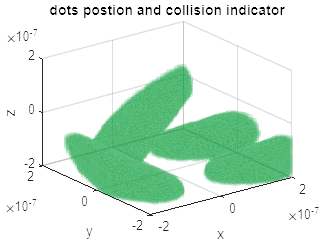

collision_fibre_fraction = total_collision_volume / total_fibre_volume;

% scatter3(dots(1,dots_in_0),dots(2,dots_in_0), dots(3,dots_in_0), '.k', 'MarkerEdgeAlpha',.01);
scatter3(dots(1,dots_in_1),dots(2,dots_in_1), dots(3,dots_in_1), "MarkerFacecolor", '#009933', 'MarkerEdgeAlpha',.0, 'MarkerFaceAlpha',.15);
hold on
scatter3(dots(1,dots_in_2),dots(2,dots_in_2), dots(3,dots_in_2), 'filled', "MarkerFacecolor", '#FFCC00', 'MarkerEdgeAlpha',.0);
scatter3(dots(1,dots_in_3),dots(2,dots_in_3), dots(3,dots_in_3), 'filled', "MarkerFacecolor", '#FF3300', 'MarkerEdgeAlpha',.0);
scatter3(dots(1,dots_in_4),dots(2,dots_in_4), dots(3,dots_in_4), 'filled', "MarkerFacecolor", '#FF66FF', 'MarkerEdgeAlpha',.0);

title('dots postion and collision indicator')
axis([-box_xyz box_xyz -box_xyz box_xyz -box_xyz box_xyz])
xlabel('x')
ylabel('y')
zlabel('z')

hold off

### Main loop

% Setting arrays for particles

in_position = zeros(3, Np);
p_position = in_position;
new_position = zeros(3, Np);
true_position = zeros(3, Np);
% true position indicators, 1 is when positive x, y or z is truely
% positve x, y or z, -1 is the inverse
true_position_indicator = ones(3, Np);

% generating 2 random angles, which are then converted into x, y and
% z positions in the loop. as the angles will be more concentrated in the
% poles, ang_1 has been adjusted to hold a more even distribution.

ang_1 = acos(2 * rand(Nt, Np) - 1);

ang_2 = 2 * pi * rand(Nt, Np);

% main loop

fibre_coordinates = [];

loading = waitbar(0, 'Starting');
for time_step = 1:Nt
    for part_num = 1:Np

        new_x = delta_r * sin(ang_1(time_step, part_num)) * cos(ang_2(time_step, part_num));
        new_y = delta_r * sin(ang_1(time_step, part_num)) * sin(ang_2(time_step, part_num));
        new_z = delta_r * cos(ang_1(time_step, part_num));
        new_position(1, part_num) = p_position(1, part_num) + new_x;
        new_position(2, part_num) = p_position(2, part_num) + new_y;
        new_position(3, part_num) = p_position(3, part_num) + new_z;

        % steps to check for collision with wall/s
        % as a particle can be in a corner, this will be repeated 3 times
        % for each cartesian position. also inverts the tp value for the
        % corresponding value

        for direction = 1:3
            % checking x,y and z positve and negative border
            if new_position(direction, part_num) > box_xyz
                dis_from_wall = new_position(direction, part_num) - box_xyz;
                new_position(direction, part_num) = new_position(direction, part_num) - 2 * dis_from_wall;

                % moves the true position to the centre of whatever cube that the point is in
                true_position(direction, part_num) = true_position(direction, part_num) + 2 * box_xyz * true_position_indicator(direction, part_num); 

                true_position_indicator(direction, part_num) = -true_position_indicator(direction, part_num);
            end
            if new_position(direction, part_num) < -box_xyz
                dis_from_wall = new_position(direction, part_num) + box_xyz;
                new_position(direction, part_num) = new_position(direction, part_num) - 2 * dis_from_wall;

                true_position(direction, part_num) = true_position(direction, part_num) - 2 * box_xyz * true_position_indicator(direction, part_num);

                true_position_indicator(direction, part_num) = -true_position_indicator(direction, part_num);
            end
        end

        % steps to check for collision with fibre

        collision_indicator = 1;
        fibre_accuracy = 2; % number of times the script will retry a particle at 0.5 the chnage in distance before it sets it back to the orignal position

        while collision_indicator == 1;

            closest_dot = zeros(3, 1);
            %determining what dot the particle is closest to, and if that
            %dot is inside a fibre
            %sorting works by finding the closest of the 1d values for each
            %direction, then multiplying them differently to find their
            %position in dot
            for dot_dir = 1:3
                min_dot = min(abs(new_position(dot_dir, part_num) - single_grid(:)));
                closest_dot(dot_dir) = find(abs(new_position(dot_dir, part_num) - single_grid(:)) == min_dot);
            end
            
            closest_dot_idx = grid_points^2 * (closest_dot(1)-1) + grid_points * (closest_dot(2)-1) + closest_dot(3);


            % if inside a fibre, will be repositioned to last halfway
            % between its old and new position, if that is still in the
            % fibre, it will move to half again, repeating untill it is out
            % of the fibre


            if fibre_check(closest_dot_idx) > 0
                if fibre_accuracy > 0
                    new_position(1, part_num) = 0.5 * (new_position(1, part_num) - p_position(1, part_num)) + p_position(1, part_num);
                    new_position(2, part_num) = 0.5 * (new_position(2, part_num) - p_position(2, part_num)) + p_position(2, part_num);
                    new_position(3, part_num) = 0.5 * (new_position(3, part_num) - p_position(3, part_num)) + p_position(3, part_num);
                    fibre_accuracy = fibre_accuracy - 1;
                elseif fibre_accuracy == 0
                    new_position(1, part_num) =  p_position(1, part_num);
                    new_position(2, part_num) =  p_position(2, part_num);
                    new_position(3, part_num) =  p_position(3, part_num);
                    collision_indicator = 0;
                end
            else
                collision_indicator = 0;
            end
            
        end

        % finally giving each point a new position
        p_position(1, part_num) = new_position(1, part_num);
        p_position(2, part_num) = new_position(2, part_num);
        p_position(3, part_num) = new_position(3, part_num);

    end
    waitbar(time_step/Nt, loading, sprintf('Progress: %d %%', floor(time_step/Nt*100)));
    pause(0.1);
end
close(loading)

### Calculations

% calculating final true postions
true_position_before = true_position;
% true_position = true_position_before;% uncomment this if re-running
% calculations

true_position = true_position + true_position_indicator .* p_position;

% DT

DT_sum_xx = 0;
for part_num = 1:Np
    DT_sum_xx = DT_sum_xx + (true_position(1, part_num) - in_position(1, part_num))^2;
end

DT_sum_yy = 0;
for part_num = 1:Np
    DT_sum_yy = DT_sum_yy + (true_position(2, part_num) - in_position(2, part_num))^2;
end

DT_sum_zz = 0;
for part_num = 1:Np
    DT_sum_zz = DT_sum_zz + (true_position(3, part_num) - in_position(3, part_num))^2;
end

DT_sum_xy = 0;
for part_num = 1:Np
    DT_sum_xy = DT_sum_xy + (true_position(1, part_num) - in_position(1, part_num)) * (true_position(2, part_num) - p_position(2, part_num));
end

DT_sum_xz = 0;
for part_num = 1:Np
    DT_sum_xz = DT_sum_xz + (true_position(1, part_num) - in_position(1, part_num)) * (true_position(3, part_num) - in_position(3, part_num));
end

DT_sum_zy = 0;
for part_num = 1:Np
    DT_sum_zy = DT_sum_zy + (true_position(3, part_num) - in_position(3, part_num)) * (true_position(2, part_num) - in_position(2, part_num));
end

DT_coeff = 1 / (2 * Np * Nt * delta_t);

% Finding DT

DT_xx = DT_coeff * DT_sum_xx;
DT_yy = DT_coeff * DT_sum_yy;
DT_zz = DT_coeff * DT_sum_zz;

DT_xy = DT_coeff * DT_sum_xy;
DT_xz = DT_coeff * DT_sum_xz;
DT_zy = DT_coeff * DT_sum_zy;

DT = [DT_xx, DT_xy, DT_xz; DT_xy, DT_yy, DT_zy; DT_xz, DT_zy, DT_zz];

% eigenvectors

[E_vec, E_val] = eig(DT);
E_val = diag(E_val);

% sorting eigenvalues, to get D1 as the eigenvalue whose eigenvector
% most allinges with the z direction. The other eigenvalues are sorted by
% how they show in the matrix, and not by size.

E_sort = sort(E_vec(3, :));

[row, col] = find(E_vec == E_sort(3));

D1 = E_val(col);

E_val_rem = E_val;
E_val_rem(E_val_rem == D1) = [];

D2 = E_val_rem(1);
D3 = E_val_rem(2);

Dl = D1 / D_0

Dl = 0.8613


Dt = mean([D2,D3]) / D_0

Dt = 0.9540


D_av = (D1 + D2 + D3) / 3;

% fractional anisotropy

FA = sqrt(3 / 2) * sqrt(((D1 - D_av)^2 + (D2 - D_av)^2 + (D3 - D_av)^2) / (D1^2 + D2^2 + D3^2))

FA = 0.0584

### **Plotting**

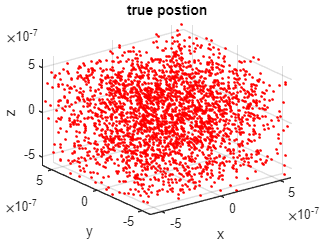

scatter = [true_position(1, :); true_position(2, :); true_position(3, :)];
k = 3; % multiplier for the size of the true position graph

scatter3(scatter(1, :),scatter(2, :), scatter(3, :), '.r')
hold on
title('true postion')
axis([-k*box_xyz k*box_xyz -k*box_xyz k*box_xyz -k*box_xyz k*box_xyz])
xlabel('x')
ylabel('y')
zlabel('z')

hold off

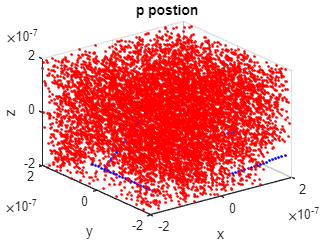

scatter = [p_position(1, :); p_position(2, :); p_position(3, :)];

fibre_1_lines = zeros(res_of_fibre, 2);
fibre_2_lines = zeros(res_of_fibre, 2);
fibre_3_lines = zeros(res_of_fibre, 2);
fibre_4_lines = zeros(res_of_fibre, 2);
z_val = zeros(res_of_fibre, 1);

for n = 1:res_of_fibre
    z_val(n) = n * 2 * box_xyz / res_of_fibre - box_xyz;
    fibre_1_lines(n, :) = [((tan(theta) * z_val(n)) * cos(phi(1))) + tan(theta) * box_xyz * cos(phi(1)) + fibre(1, 1)
        , ((tan(theta) * z_val(n)) * sin(phi(1))) + tan(theta) * box_xyz * sin(phi(1)) + fibre(1, 2)];

    fibre_2_lines(n, :) = [((tan(theta) * z_val(n)) * cos(phi(2))) + tan(theta) * box_xyz * cos(phi(2)) + fibre(2, 1)
        , ((tan(theta) * z_val(n)) * sin(phi(2))) + tan(theta) * box_xyz * sin(phi(2)) + fibre(2, 2)];

    fibre_3_lines(n, :) = [((tan(theta) * z_val(n)) * cos(phi(3))) + tan(theta) * box_xyz * cos(phi(3)) + fibre(3, 1)
        , ((tan(theta) * z_val(n)) * sin(phi(3))) + tan(theta) * box_xyz * sin(phi(3)) + fibre(3, 2)];

    fibre_4_lines(n, :) = [((tan(theta) * z_val(n)) * cos(phi(4))) + tan(theta) * box_xyz * cos(phi(4)) + fibre(4, 1)
        , ((tan(theta) * z_val(n)) * sin(phi(4))) + tan(theta) * box_xyz * sin(phi(4)) + fibre(4, 2)];
end


scatter3(scatter(1, :),scatter(2, :), scatter(3, :), '.r')
hold on
scatter3(fibre_1_lines(:,1), fibre_1_lines(:,2), z_val(:), '.b')
scatter3(fibre_2_lines(:,1), fibre_2_lines(:,2), z_val(:), '.b')
scatter3(fibre_3_lines(:,1), fibre_3_lines(:,2), z_val(:), '.b')
scatter3(fibre_4_lines(:,1), fibre_4_lines(:,2), z_val(:), '.b')
title('p postion')
axis([-box_xyz box_xyz -box_xyz box_xyz -box_xyz box_xyz])
xlabel('x')
ylabel('y')
zlabel('z')

hold off

### **Saving Data**

% saves all of the variables, but larger ang_1 and ang_2 values. These are
% all of the angles used to do the random walk, and are not important in
% data analysis.

%save("C:/Users/eddie/Documents/MATLAB/AC Diffusion/Data/S_Test_" + num2str(Nt) + "_" + num2str(Np) + "_" + num2str(rad2deg(theta)) + "_" + ...
%    num2str(test_num)); %This value must be changed for each test, otherwise the data will be overwritten
